# Task 1: Gather starter assumptions and load material properties



clear; clc;

% Load material property data
load("C:\Users\PhotonUser\My Files\Temporary Files\droneArmMaterials.mat");


% Display loaded variables
whos

  Name           Size            Bytes  Class     Attributes

  materials      1x6              5829  struct              



disp(materials)

  1×6 struct array with fields:

    name
    rho_kg_m3
    E_Pa
    nu
    yieldStrength_Pa
    cost_USD_per_m



## Given drone design parameters



numMotors = 4;
numPropellers = 4;

g = 9.81;                          % acceleration due to gravity, m/s^2

maxThrustPerMotor_kg = 1;          % kg thrust per motor
maxThrustPerMotor_N = maxThrustPerMotor_kg * g;
totalMaxThrust_N = numMotors * maxThrustPerMotor_N;

baseDroneMass_kg = 1.0;            % drone mass excluding arms and payload

batteryMass_kg = 0.30;
motorMass_each_kg = 0.065;
propellerMass_each_kg = 0.010;
escMass_each_kg = 0.030;
flightControllerMass_kg = 0.050;
receiverGPSMass_kg = 0.030;
centerFrameMass_kg = 0.200;

baseMassCheck_kg = batteryMass_kg + ...
                   numMotors*motorMass_each_kg + ...
                   numPropellers*propellerMass_each_kg + ...
                   numMotors*escMass_each_kg + ...
                   flightControllerMass_kg + ...
                   receiverGPSMass_kg + ...
                   centerFrameMass_kg;


## Project requirements



minimumPayload_kg = 0.5;
requiredThrustToWeightRatio = 2.0;


## Display key values


fprintf("Total maximum thrust = %.2f N\n", totalMaxThrust_N);

Total maximum thrust = 39.24 N


fprintf("Base drone mass check = %.2f kg\n", baseMassCheck_kg);

Base drone mass check = 1.00 kg


fprintf("Minimum payload requirement = %.2f kg\n", minimumPayload_kg);

Minimum payload requirement = 0.50 kg


fprintf("Required thrust-to-weight ratio = %.1f:1\n", requiredThrustToWeightRatio);

Required thrust-to-weight ratio = 2.0:1


## Task 3: Thrust-to-weight analysis across design and material options



% Assumptions from project
numMotors = 4;
maxThrustPerMotor_kg = 1;     % kg thrust
totalThrust_kg = numMotors * maxThrustPerMotor_kg;

requiredTWR = 2.0;
baseDroneMass_kg = 1.0;
minimumPayload_kg = 0.5;

% Maximum total drone mass allowed by 2:1 thrust-to-weight ratio
maxAllowedTotalMass_kg = totalThrust_kg / requiredTWR;

fprintf("Maximum allowed total drone mass = %.2f kg\n", maxAllowedTotalMass_kg);

Maximum allowed total drone mass = 2.00 kg


## Design B: Hollow tube with pads



% Tube
tubeLength_B = 0.25;       % m
outerD_B = 0.025;          % m
innerD_B = 0.019;          % m
tubeArea_B = (pi/4) * (outerD_B^2 - innerD_B^2);
tubeVolume_B = tubeArea_B * tubeLength_B;

% Body pad: 35 mm x 35 mm x 6 mm
bodyPadVolume_B = 0.035 * 0.035 * 0.006;

% Motor pad: circular disk, 40 mm diameter x 6 mm thick
motorPadD_B = 0.040;
motorPadT_B = 0.006;
motorPadVolume_B = (pi/4) * motorPadD_B^2 * motorPadT_B;

% Total volume of one arm
volume_B = tubeVolume_B + bodyPadVolume_B + motorPadVolume_B;

fprintf("Design B tube with pads volume = %.8f m^3\n", volume_B);

Design B tube with pads volume = 0.00006673 m^3


armVolume = volume_B;   % Design B hollow circular tube with pads

## Calculate Design B mass for each material

%% Calculate Design B mass for each material

numMaterials = length(materials);

materialName = strings(numMaterials,1);
armMass = zeros(numMaterials,1);
totalArmMass = zeros(numMaterials,1);
payloadCapacity = zeros(numMaterials,1);

for i = 1:numMaterials
    
    % Use the actual field names from your materials file
    density = materials(i).rho_kg_m3;
    
    % Mass of one arm
    armMass(i) = density * armVolume;
    
    % Mass of four arms
    totalArmMass(i) = 4 * armMass(i);
    
    % Maximum payload capacity
    payloadCapacity(i) = maxAllowedTotalMass_kg - baseDroneMass_kg - totalArmMass(i);
    
    % Material name
    materialName(i) = string(materials(i).name);

end
results = table(materialName, armMass, totalArmMass, payloadCapacity,...
    'VariableNames', {'Material','OneArmMass_kg','TotalArmMass_kg','MaxPayload_kg'});

disp(results)

               Material                OneArmMass_kg    TotalArmMass_kg    MaxPayload_kg
    _______________________________    _____________    _______________    _____________

    "Carbon Fiber Composite (CFRP)"       0.10676           0.42705           0.57295   
    "Aluminum Alloy"                      0.18016           0.72064           0.27936   
    "Fiberglass Composite (GFRP)"         0.12678           0.50712           0.49288   
    "PLA Plastic"                        0.083408           0.33363           0.66637   
    "ABS Plastic"                        0.070062           0.28025           0.71975   
    "Wood (Birch)"                       0.040036           0.16014           0.83986   



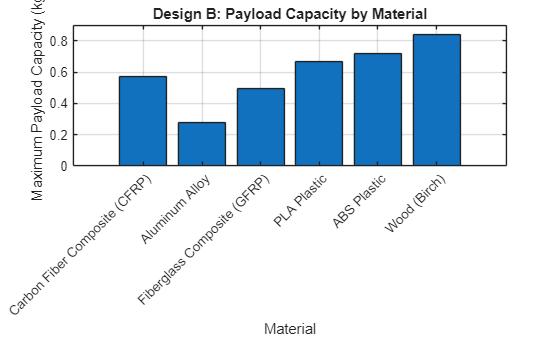

%% Plot payload capacity

figure

bar(payloadCapacity)

xticklabels(materialName)
xtickangle(45)

ylabel("Maximum Payload Capacity (kg)")
xlabel("Material")

title("Design B: Payload Capacity by Material")

grid on